# State feedback and MATLAB tools 

The control101 toolbox focuses mainly on linear models and thus simple MATLAB code is sufficient to illustrate the core behaviours and analysis. A common linear model type is the state space model. 

When a system is expressed as a state-space model, it is normal to design the closed-loop compensator as a state feedback. This file gives an introduction to the topic and  relevant MATLAB code to support the associated feedback design. As ever, use text books for more detail on the theoretical aspects and MATLAB provides short cut files which can be used for efficient coding in the long  term.

Because the file focuses on pole placement, mathematically the continuous and discrete cases are identical and thus identical code will work in both cases.

Lots of code snippets are provided as examples of how MATLAB can be used and the intention is that readers can use these as exemplars and/or templates and change the models and scenarios for their own need.

### Similar files and the toolbox

See website below for more files like this.     [https://sites.google.com/sheffield.ac.uk/controleducation/matlabresources/section-6-11-community-control-toolbox](https://sites.google.com/sheffield.ac.uk/controleducation/matlabresources/section-6-11-community-control-toolbox)

This group of files can also be downloaded through MATLAB add-ons with the toolbox name:  **control101**

**For more information on those files  uncomment and run either line of the code below (using run section):**

% doc Control101 Toolbox  % this line works even if toolbox not installed
%
% There is a bug in 2024a: Try doc ("Control101 Toolbox")  or doc control101_toolbox. 
%
% help control101  % this line only works if the toolbox is installed

File written by J.A.Rossiter, Ross Drummond, Lanlan Su (University of Sheffield) and Ruth Bars ( Budapest University of Technology and Economics)                           

## Table of Contents

1. Background on concepts of state feedback

2. Pole placement methods

    2.1 A simplified approach

    2.2 A simplified approach with canonical forms

    2.3 Exploiting transformations when the system is not in canonical form 

    2.4 Ackermanns formula

    2.5 Using MATLAB built in functionality

Appendix: Examples of why pole placement is difficult in practice

## 1. Background on concepts of state feedback

This resource assumes a state-space model of the form:

$\dot{X} =A\;X+B\;U;\;Y=C\;X+D\;U,\;$with state *X*, input *U* and output *Y. *

The target in general is to control the system behaviour and thus one adopts feedback of some form which measures the output and then makes suitable choices to the input. However, with state-space systems it is more normal to base feedback on the state rather than the output; for now assume the state is known and later resources will deal with how to estimate this.

In summary, a typical state feedback takes the form below (for both the continuous-time and discrete-time cases):


$$U=-K\;X$$


**Remark**: As this resource introduces the basic concepts, it is best to focus on regulation control, that is driving the state to the origin. Later resources will introduce non-zero targets, model uncertainty and more.

Substituting the state feedback above into the model results in the following closed-loop model:

$\dot{X} =\left(A-B\;K\right)\;X;\;\;\;Y=C\;X+D\;U,\;\;U=-K\;X;\;\;\;\;K=\left\lbrack \begin{array}{ccc}
k_1  & k_2  & \cdots 
\end{array}\right\rbrack$;   

Hence, the core question to deal with is: how might the state feedback matrix *K *be selected?

**Remark**: As befits an introductory resource, this resource assumes all the state-space models are in minimal form and thus are both controllable and observable (e.g. ***controllability_and_observability_control101***).

**Remark**: We know from earlier resources (e.g.  ***openloop_behaviour_statespace_control101***) that the closed-loop poles are derived from the eigenvalues, that is the design will be focussed on choosing appropriate positions for $\lambda$ where: $\left|\lambda I-A+B\;K\right|=0$.  Mathematically the continuous-time and discrete-time cases are identical for this analysis and thus the identical equation can be used in both cases.

It is important to note a core property that will not be proved but is used implicitly. If a system is controllable, then it is possible to place the poles arbitrarily through the use of state feedback gain *K*. What is needed is a methodology for determining the appropriate values for *K*.

## 2. Pole placement methods

Pole placement methods assume that, by some method, it is possible to determine suitable closed-loop poles. The design then reduces to finding a suitable value for *K* to achieve these poles. Neverthless, it should be pointed out that in reality pole placement is a first step in understanding state feedback which demonstrates numerous important properties to be utilised later. In the longer term, other design methods are to be prefered as choosing all the desired closed-loop pole positions cannot be done sensibly in general for most real systems. ** See appendix for some worked examples.**

**Summary design approach**: Assume the following model and feedback $\dot{X} =\left(A-B\;K\right)X;\;\;\;Y=C\;X+D\;U,\;\;U=-K\;X$ and a set of target poles $p_1 ,p_2 ,\cdots$. Find the state feedback *K* so that   $\left|p_i I-A+B\;K\right|=0$ for all the target poles.

**Remark**: Although all the examples given here are for the continuous-time case, one can easily swap the *A, B* matrices for discrete-time equivalents and use exactly the same code, but of course with suitably defined pole positions for the discrete-time case.

### 2.1 A simplified approach

For low order systems it is possible to create a formulae for $\left|\lambda I-A+B\;K\right|=0$ and thus define conditions for each parameter of *K*. For example:


$$A=\left\lbrack \begin{array}{cc}
1 & 2\\
1 & 0
\end{array}\right\rbrack ;\;B=\left\lbrack \begin{array}{c}
-2\\
3
\end{array}\right\rbrack \;\;\;\Rightarrow \;\;$$

$$\left|\lambda I-A+B\;K\right|=\lambda^2 -\left(1+2k_1 -3k_2 \right)\lambda -\left(1+2k_1 \right)k_2 -\left(2+2k_2 \right)\left(1-3k_1 \right)=0$$


Thus one can determine suitable values for *K* such that  $p_1 ,p_2$ are solutions. Of course the reader will notice immediately that while this will work in principle, the associated algebra will quickly become unmanageable with larger state dimensions. We need to be able to express this problem in a more insightful manner. Try extending the examples below to higher dimensions and solving for the required $k_i$.

disp('Section 2.1 - impact of state feedback on characteristic polynomial')

Section 2.1 - impact of state feedback on characteristic polynomial


A=[1 2;1 0]; B=[-2;3];
syms k1 k2 s
K=[k1 k2];
closed_loop_polynomial=det(s*eye(2)-A+B*K)

$$closed\_loop\_polynomial = 6\,k_{1}-5\,k_{2}-s-2\,k_{1}\,s+3\,k_{2}\,s+s^{2}-2$$


A=[1 2 3;1 0 -1;2 -0.4 2]; B=[-2;3;0];
syms k1 k2 k3 s
K=[k1 k2 k3];
closed_loop_polynomial=det(s*eye(3)-A+B*K)

$$closed\_loop\_polynomial = 14\,k_{3}-4\,k_{2}-\frac{74\,k_{1}}{5}-\frac{32\,s}{5}+10\,k_{1}\,s-11\,k_{2}\,s-\frac{26\,k_{3}\,s}{5}-2\,k_{1}\,s^{2}+3\,k_{2}\,s^{2}-3\,s^{2}+s^{3}+\frac{48}{5}$$

### 2.2 A simplified approach with canonical forms

If a system is expressed in control canonical form, then state feedback becomes much easier as there is a simple link between the parameters of *K* and the parameters of the closed-loop pole polynomial which can be exploited. These links are discussed in the files ***statespace_models_from_tf_control101, tf_models_from_statespace_control101***.  In simple terms, the parameters of the characteristic polynomial appear in a single row of the *A* matrix.

For example the transfer function model $Y\left(s\right)=\frac{b}{s^3 +a_1 s^2 +a_2 s+a_3 }U\left(s\right)$ gives rise to the state-space model: 


$$A=\left\lbrack \begin{array}{ccc}
{-a}_1  & {-a}_2  & {-a}_3 \\
1 & 0 & 0\\
0 & 1 & 0
\end{array}\right\rbrack ;\;\;B=\left\lbrack \begin{array}{c}
1\\
0\\
0
\end{array}\right\rbrack ;\;C=\left\lbrack \begin{array}{ccc}
0 & 0 & b
\end{array}\right\rbrack ;\;\;D=0$$


Adding state feedback $U=-K\;X$ gives rise to the closed-loop model:


$$A-B\;K=\left\lbrack \begin{array}{ccc}
{-a}_1 -k_1  & {-a}_2 -k_2  & {-a}_3 -k_3 \\
1 & 0 & 0\\
0 & 1 & 0
\end{array}\right\rbrack \;\;\;\;\Rightarrow \;G_c \left(s\right)=$$

$$\frac{b}{s^3 +\left(a_1 +k_1 \right)s^2 +\left(a_2 +k_2 \right)s+\left(a_3 +k_3 \right)}$$


One can see therefore that there is a simple and explicit link between the state feedback parameters and the coefficients of the characteristic polynomial. Hence: 

- First define the desired characteristic polynomial, for example: $p\left(s\right)=\left(s-p_1 \right)\left(s-p_s \right)\cdots \;=s^n +d_1 s^{n-1} +d_2 s^{n-2} +\cdots$

- Then solve, for each index: $d_1 =\left(a_1 +k_1 \right),d_2 =\left(a_2 +k_2 \right),\cdots$.

Using MATLAB tools this can be done quickly and efficiently as shown below. You will see that the link between the parameters of the open and closed-loop pole polynomials is simply the addition of the vector K.

disp('Section 2.2 examples of state feedback on a canonical form')

Section 2.2 examples of state feedback on a canonical form


disp('First example')

First example


syms s
A=[1 2;1 0];
B=[1;0];
K=[4 4]

K =      4     4


popen=det(s*eye(2)-A)

$$popen = s^{2}-s-2$$

pclosed=det(s*eye(2)-A+B*K)

$$pclosed = s^{2}+3\,s+2$$



% example 2
disp('2nd example')

2nd example


A=[1 3 3;1 0 0; 0 1 0]; 
B=[1;0;0];
K=[4 6 3]

K =      4     6     3


popen=det(s*eye(3)-A)

$$popen = s^{3}-s^{2}-3\,s-3$$

pclosed=det(s*eye(3)-A+B*K)

$$pclosed = s^{3}+3\,s^{2}+3\,s$$


disp('Automating the choice of K')

Automating the choice of K


Choosepoles = [-1,-2,-3];
Desired_closedloop_polynomial = poly(Choosepoles)

Desired_closedloop_polynomial =      1     6    11     6


K=Desired_closedloop_polynomial(2:end)+A(1,:)   % Choice of K linked to desired polynomial

K =      7    14     9


Achieved_polynomial=det(s*eye(3)-A+B*K)

$$Achieved\_polynomial = s^{3}+6\,s^{2}+11\,s+6$$

### 2.3 Exploiting transformations when the system is not in canonical form 

In reality the state-space model will not usually be in canonical form so the method of section 2.2 cannot be applied immediately. However, readers will remember the previous file ***equivalent_state_space_formulations_control101*** which showed that, assuming the system is in minimal form, one can always find a state transformation to create the equivalent canonical form. Hence a simple design appropach can be proposed.

- Convert the model to canonical form; this could be done using transfer function equivalents for SISO systems.

- Find the state feedback in canonical form using the technique of section 2.2 above.

- Find the transformation from the orginal system to canonical form.

- Convert the state feedback to operate on the states of the original system.

The algebra for steps 3-4  is summarised concisely here.

- Define a transformation to convert to canonical form: $Z=T\;X$. Now the equivalent model is given as: $\dot{Z} =\hat{\mathrm{A}} \;Z+\hat{\mathrm{B}} \;U;\;Y=\hat{\mathrm{C}} \;Z+\hat{\mathrm{D}\;} U$ with $\hat{A} =T\;AT^{-1} ;\;\;\;\hat{B} =T\;B;\;\;\hat{C} =CT^{-1}$.

- Define the controllability matrices for the transformed and non-transformed systems. $M=\left\lbrack B,A\;B,A^2 B,\ldotp \ldotp \ldotp \right\rbrack ;\;\hat{M} =\left\lbrack \hat{B} ,\hat{A} \hat{B} ,{\hat{A} }^2 \hat{B} ,\ldotp \ldotp \ldotp \right\rbrack$.

- Note that:  $T=M^{-1} \hat{M}$

- In canonical form, the state feedback is:  $U=-K\;Z\ldotp \;$ Thus in terms of the original state the feedback is: $U=-K\;T\;X$.

disp('Section 2.3: Example 1')

Section 2.3: Example 1


A=[-1 -2;1 -0.4]; B=[1;-2];C=[3,4];D=0;
% find canonical form
[n,d]=ss2tf(A,B,C,D,1); 
[Ahat,Bhat,Chat,Dhat]=tf2ss(n,d); Ahat

Ahat =    -1.4000   -2.4000
    1.0000         0


% define state fbk in canonical state-space and confirm correct poles
charpoly = [1 3 2];
Khat=charpoly(2:end)+Ahat(1,:)

Khat =     1.6000   -0.4000


closed_loop_poles_with_Khat = eig(Ahat-Bhat*Khat)

closed_loop_poles_with_Khat =     -2
    -1


% Use controllability matrices to find state feedback in original state
% space
Mx=ctrb(A,B);
Mz=ctrb(Ahat,Bhat);
T=Mz*inv(Mx);
K=Khat*T

K =    -0.3077   -0.9538


closed_loop_poles_with_K = eig(A-B*K)

closed_loop_poles_with_K =    -1.0000
   -2.0000


disp('Section 2.3: Example 2')

Section 2.3: Example 2


A=[-1 -2 -0.5;0.2 -0.4 -0.6;0 -0.1 0.4]; 
B=[1;-1;0];C=[1,3,4];D=0;
% find canonical form
[n,d]=ss2tf(A,B,C,D,1);
[Ahat,Bhat,Chat,Dhat]=tf2ss(n,d);
% define state fbk in canonical state-space and confirm correct poles
charpoly=poly([-0.5,-1,-1.5])

charpoly =     1.0000    3.0000    2.7500    0.7500


Khat=[charpoly(2:end)]+Ahat(1,:)

Khat =     2.0000    2.5700    1.1400


closed_loop_poles_Khat =eig(Ahat-Bhat*Khat)

closed_loop_poles_Khat =    -1.5000
   -1.0000
   -0.5000


% Use controllability matrices to find state feedback in original state
% space
Mx=ctrb(A,B);
Mz=ctrb(Ahat,Bhat);
T=Mz*inv(Mx);
K=Khat*T

K =    -0.1793   -2.1793   20.5690


closed_loop_poles_K =eig(A-B*K)

closed_loop_poles_K =    -1.5000
   -1.0000
   -0.5000


### 2.4 Ackermanns formula

This approach is introduced concisely just because it is very easy to code in MATLAB and avoids the need to use the canonical form and to find the associated transformations. Readers are referred to the text books for a detailed background and explanation of why this method works.

- Define the desired closed-loop pole polynomial as: $p_c \left(s\right)=\left(s-p_1 \right)\left(s-p_s \right)\cdots \;=s^n +d_1 s^{n-1} +d_2 s^{n-2} +\cdots$

- Compute the matrix: $p_c \left(A\right)=A^n +d_1 A^{n-1} +\cdots$

- Define the controllability matrix: $M=\left\lbrack B,A\;B,A^2 B,\ldotp \ldotp \ldotp \right\rbrack$

- Define the required state feedback using the formula: $K=\left\lbrack \begin{array}{ccccc}
0 & 0 & \cdots  & 0 & 1
\end{array}\right\rbrack M^{-1} p_c \left(A\right)$

Some examples will show that this works.

disp('Section 2.4: Examples of using Ackermanns formula')

Section 2.4: Examples of using Ackermanns formula


%% Example 1
A=[-1 -2;1 -0.4]; B=[1;-2];
C=[3,4];D=0;
Mx=ctrb(A,B);
% desired poly is [1 3 2]
PcA=A^2+3*A+2*eye(2);
K=[0 1]*inv(Mx)*PcA

K =    -0.3077   -0.9538


closed_loop_poles=eig(A-B*K)

closed_loop_poles =    -1.0000
   -2.0000



%%% Example 2
A=[-1 -2 -0.5;0.2 -0.4 -0.6;0 -0.1 0.4]; 
B=[1;-1;0];C=[1,3,4];D=0;
desired_poly=poly([-0.5,-1,-1.5]);
Mx=ctrb(A,B);
PcA=A^3+desired_poly(2)*A^2+desired_poly(3)*A+desired_poly(4)*eye(3)

PcA =    -0.2300    0.5600    1.7150
   -0.0460   -0.2480   -1.7420
   -0.0400   -0.2570    2.6080


K=[0 0 1]*inv(Mx)*PcA

K =    -0.1793   -2.1793   20.5690


closed_loop_poles=eig(A-B*K)

closed_loop_poles =    -1.5000
   -1.0000
   -0.5000


### 2.5 Using MATLAB built in functionality

As expected, once students are familiar with the underlying theory and algorithms, MATLAB provides short cut files to derive the required state feedback in one simple statement. In this case there are two possible file choices: 

***K = place(A,B,targetpoles)   [May not work well with repeated poles]***

***K = acker(A,B,targetpoles)   [Specifically uses Ackermanns formula]***

That is, simply provide the *A, B* matrices alongside the desired poles, and the state feedback will be given. Compare the answers below to those given in section 2.3 above.

disp('Section 2.5: Examples from previous subsection showing the same answers')

Section 2.5: Examples from previous subsection showing the same answers


A=[-1 -2;1 -0.4]; B=[1;-2];
charpoles = [-1 -2]';
K=place(A,B,charpoles)

K =    -0.3077   -0.9538


Ka=acker(A,B,charpoles)

Ka =    -0.3077   -0.9538



A=[-1 -2 -0.5;0.2 -0.4 -0.6;0 -0.1 0.4]; 
B=[1;-1;0];
charpoles=[-0.5,-1,-1.5];
K=place(A,B,charpoles)

K =    -0.1793   -2.1793   20.5690


Ka=acker(A,B,charpoles)

Ka =    -0.1793   -2.1793   20.5690



disp('Example with complex pole choices')

Example with complex pole choices


A=[0 1;0 0]; B=[0;1];
poles=[-1+0.5j,-1-0.5j]

poles =   -1.0000 + 0.5000i  -1.0000 - 0.5000i


K = place(A,B,poles)

K =     1.2500    2.0000


Ka = acker(A,B,poles)

Ka =     1.2500    2.0000



disp('Example with repeated poles using only Ackermann')

Example with repeated poles using only Ackermann


A=[-6 -11 -6;1 -0 -0;0 1 0]; 
B=[1;0;0];
poles=[-2,-2,-2]

poles =     -2    -2    -2


Ka = acker(A,B,poles)

Ka =      0     1     2


## Appendix: Examples of why pole placement is difficult in practice

The following example explores the behaviour with a range of possible closed-loop poles, using pole placement to assign those poles. It is clear, that in general, it would be difficult to use the pole position choices as part of a systematic design approach. We need to know good pole choices before we start!

disp('APPENDIX: Regulation control with pole-placement feedback design with varying pole choices');

APPENDIX: Regulation control with pole-placement feedback design with varying pole choices


disp('The plots show the trajectories for different possible output choices (that is different C)')

The plots show the trajectories for different possible output choices (that is different C)


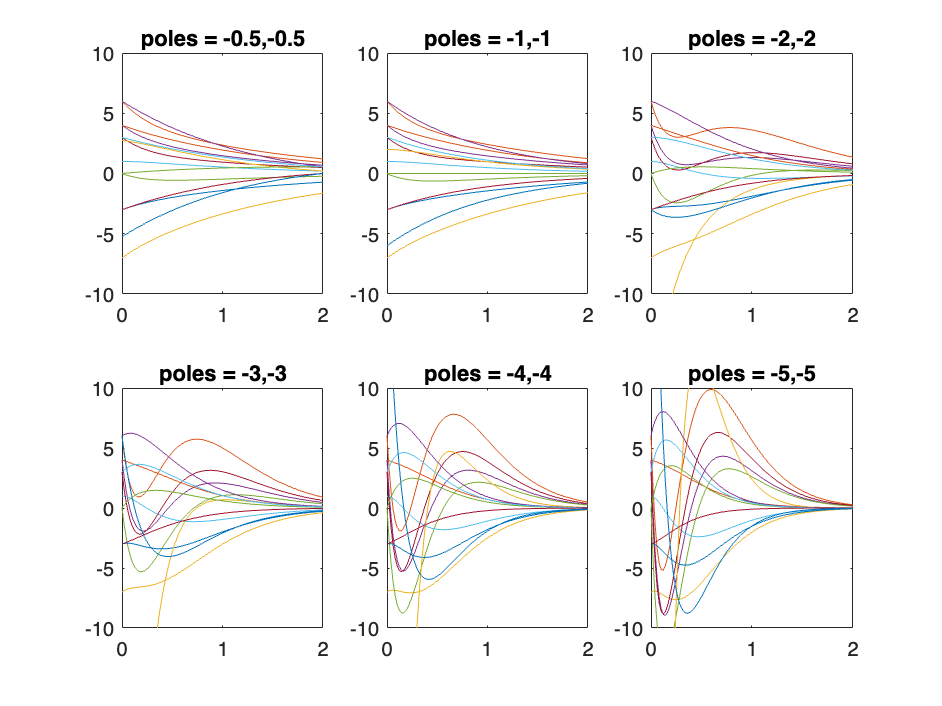

A=[-1 -2;1 0]; B=[1;0];C=[1 -1;1 1; 1 0; 0 1];
p=[-0.5,-1,-2,-3,-4,-5];
q=p;
t=linspace(0,2,100);
u=t*0;
x0=[3;-3];


for k=1:6
K=[-1-p(k)-q(k) -2+p(k)*q(k)];
CC=[C;-K];    
Phi=A-B*K;
[y,t]=lsim(ss(A-B*K,B,CC,0),u,t,x0);
subplot(2,3,k);
plot(t,y); hold on
tt{k}=['poles = ',num2str(p(k)),',',num2str(q(k))];
title(tt{k})
end
hold off


disp('Same example, different choices of poles')

Same example, different choices of poles


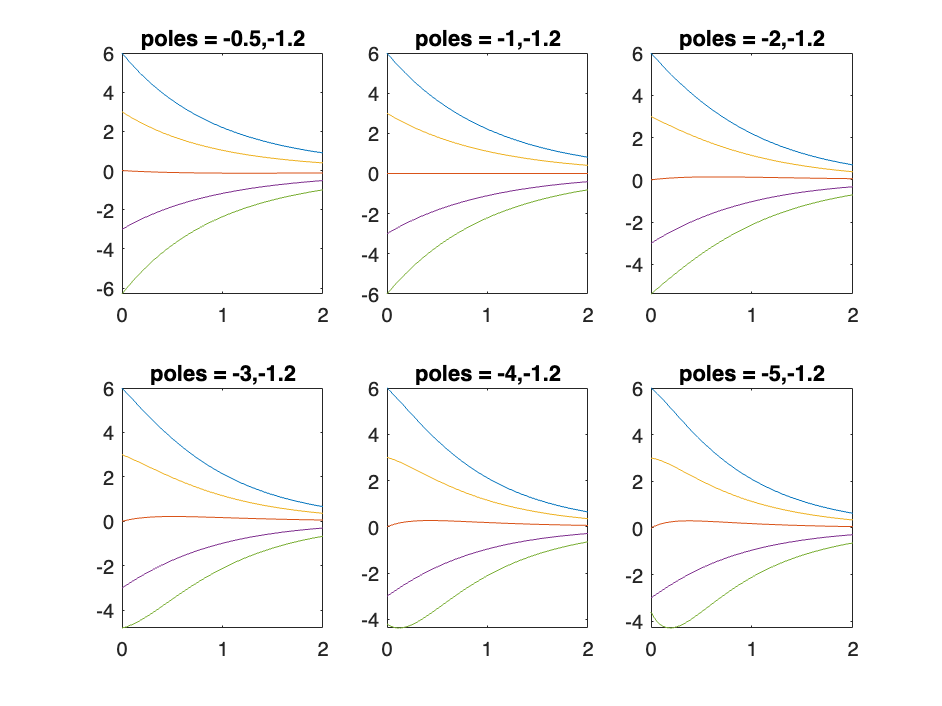

p=[-0.5,-1,-2,-3,-4,-5];
q=[-1.2,-1.2,-1.2,-1.2,-1.2,-1.2];
figure
for k=1:6
K=[-1-p(k)-q(k) -2+p(k)*q(k)];
CC=[C;-K];    
Phi=A-B*K;
[y,t]=lsim(ss(A-B*K,B,CC,0),u,t,x0);
subplot(2,3,k);
plot(t,y); hold on
tt{k}=['poles = ',num2str(p(k)),',',num2str(q(k))];
title(tt{k})
end
hold off


disp('Higher order example')

Higher order example


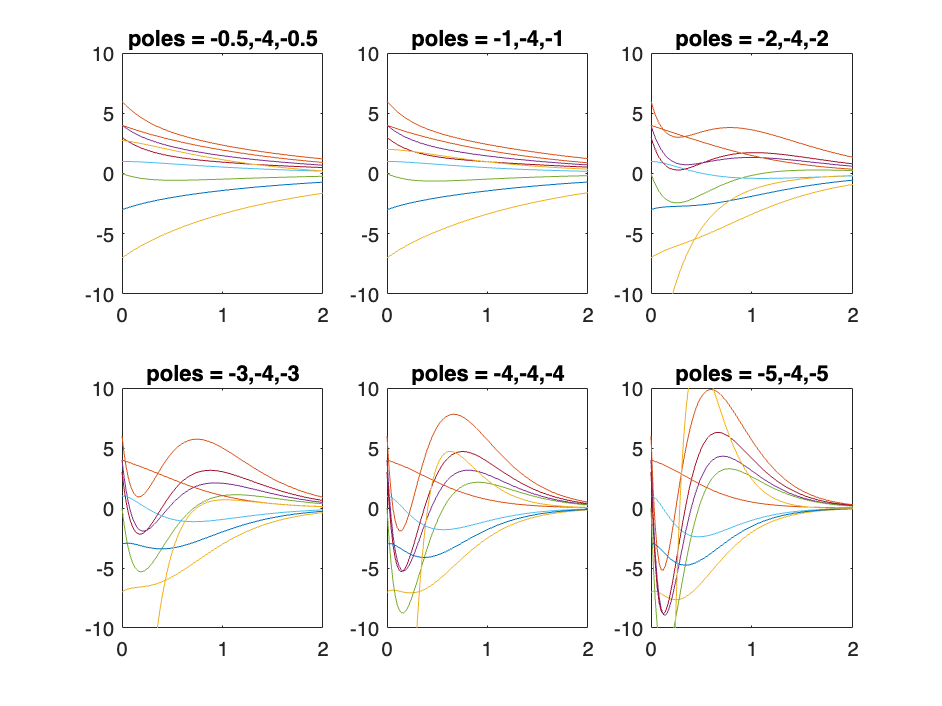

A=[-6 -11 -6;1 0 0;0 1 0]; 
B=[1;0;0];
C=[1 -1 0;1 -1 0; 0 1 -1; 1 1 1;1 1 0;0 1 1;eye(3)];
p=[-0.5,-1,-2,-3,-4,-5];
q=[-4,-4,-4,-4,-4,-4];
r=p;
figure
x0=[3;-3;4];
for k=1:6
    pp=poly([p(k),q(k),r(k)]);
K=[-6+pp(2) -11+pp(3),-6+pp(4)];
CC=[C;-K];    
Phi=A-B*K;
[y,t]=lsim(ss(A-B*K,B,CC,0),u,t,x0);
subplot(2,3,k);
plot(t,y); hold on
tt{k}=['poles = ',num2str(p(k)),',',num2str(q(k)),',',num2str(r(k))];
title(tt{k})
ylim([-10,10]);
end